d = inputs;
mp = mesh_points(d.number_of_points_array);



explicit = read2Dmatrix("exports\2D\100_explicit.csv", d);
s0_explicit = read2Dmatrix("exports\2D\s0_100_explicit.csv", d);
s1_explicit = read2Dmatrix("exports\2D\s1_100_explicit.csv", d);
% s2_explicit = read2Dmatrix("exports\2D\s0.30103_100_explicit.csv", d);
% s3_explicit = readmatrix("exports\1D\s-3_100_explicit.csv");


## Parâmetros das imagens

space = linspace(0, d.total_distance, d.number_of_points_array);
max_time  = mp.t_number_of_points;
step_time = floor(mp.t_number_of_points/20);
MIN_DOSE_THRESHOLD = 1E-1;
MIN_CONCENTRATION_THRESHOLD = 1E-3;


## Controle

TIME_CONTROL =198;

## Determinístico

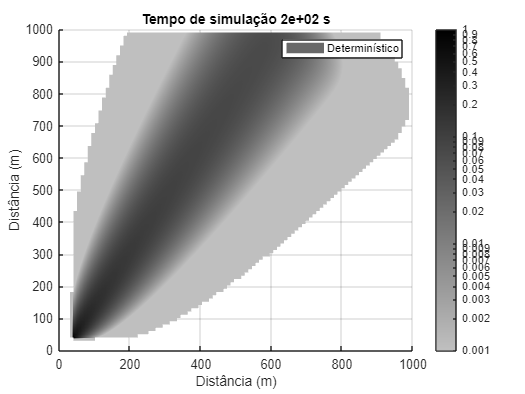

surf(mp.x_grid, mp.y_grid, explicit(:,:,TIME_CONTROL));

set(gca,'ColorScale','log');
shading interp

view(2);
xlim([0,d.total_distance]);
ylim([0,d.total_distance]);

xlabel('Distância (m)'); 
ylabel('Distância (m)'); 
zlabel('Concentração (Bq/m³)');

title("Tempo de simulação " + num2str(TIME_CONTROL*mp.delta_t, 2) + " s");

colormap(custom_gray)
cl = colorbar;

concentration_ticks = colorbar_ticks(MIN_CONCENTRATION_THRESHOLD, max_concentration);
cl.Ticks = concentration_ticks;
cl.TickLabels = num2cell(concentration_ticks);

clim([MIN_CONCENTRATION_THRESHOLD d.C_x1]);
% hold on 
% 
% surf(mp.x_grid, mp.y_grid, s0_explicit(:,:,TIME_CONTROL));
% shading interp
% plot(space,s1_explicit(:, TIME_CONTROL), 'r--','LineWidth',1.5);
% plot(space,s2_explicit(:, TIME_CONTROL), 'g--','LineWidth',1.5);
% plot(space,s3_explicit(:, TIME_CONTROL), 'b--','LineWidth',1.5);

hold off

legend('Determinístico')

## Estocástico

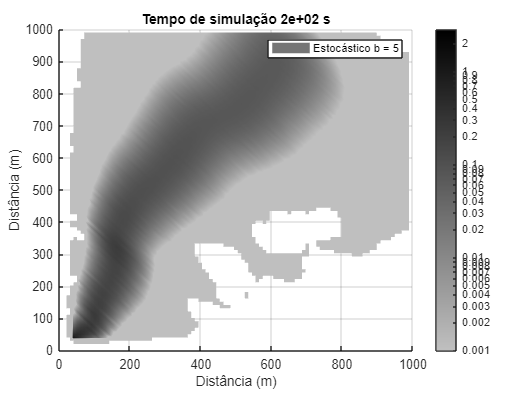

surf(mp.x_grid, mp.y_grid, s0_explicit(:,:,TIME_CONTROL));

set(gca,'ColorScale','log');
shading interp

view(2);
xlim([0,d.total_distance]);
ylim([0,d.total_distance]);

xlabel('Distância (m)'); 
ylabel('Distância (m)'); 
zlabel('Concentração (Bq/m³)');

title("Tempo de simulação " + num2str(TIME_CONTROL*mp.delta_t, 2) + " s");

colormap(custom_gray)
cl = colorbar;

concentration_ticks = colorbar_ticks(MIN_CONCENTRATION_THRESHOLD, max_concentration);
cl.Ticks = concentration_ticks;
cl.TickLabels = num2cell(concentration_ticks);

clim([MIN_CONCENTRATION_THRESHOLD max_concentration]);


legend('Estocástico b = 5')

## Diferença Determinístico vs. Estocástico

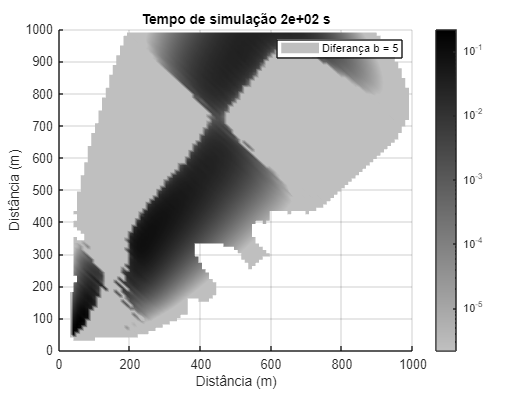


error0 = (explicit - s0_explicit);
% error1 = explicit - s1_explicit;
% error2 = explicit - s2_explicit;
% error3 = explicit - s3_explicit;
% relative_error = error./explicit;
% relative_error(relative_error == -Inf) = 0;

surf(mp.x_grid, mp.y_grid, error0(:,:,TIME_CONTROL));

set(gca,'ColorScale','log');
shading interp

view(2);
xlim([0,d.total_distance]);
ylim([0,d.total_distance]);

xlabel('Distância (m)'); 
ylabel('Distância (m)'); 
zlabel('Concentração (Bq/m³)');

title("Tempo de simulação " + num2str(TIME_CONTROL*mp.delta_t, 2) + " s");

colormap(custom_gray)
cl = colorbar;

legend('Diferança b = 5')

## Função pra ler matriz 2D

function matrix = read2Dmatrix(filename, input)
    matrix = readmatrix(filename);
    matrix = reshape(matrix, input.number_of_points_array, input.number_of_points_array, []);
end
